# Lights peaks

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

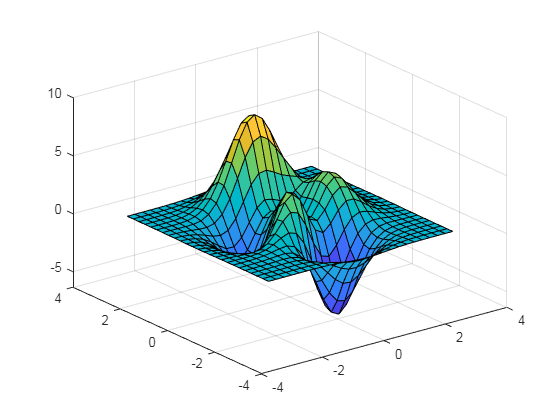

pl.scene_begin('scene_file', 'lights_peaks.pov', 'image_file', 'lights_peaks.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    pl.camera('angle', 25, 'location', [24 20 15], 'look_at', [0 0 2.5], 'type', 'perspective');
    pl.light('location',  [10 10 10], 'color', [1 1 1]);
        
    % Light marks
    nmarks = 25;
    [x,y,z] = peaks(nmarks);
    surf(x,y,z);

    zmax = max(z, [], 'all');
    for i = 1:nmarks
        for j = 1:nmarks
            pl.sphere('position', [x(i,j) y(i,j) z(i,j)], 'radius', 0.1, 'texture', 'NBwinebottle', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
            pl.light('location',  [x(i,j) y(i,j) z(i,j)], 'color', [0.1 0.1 z(i,j) ./ zmax]);
        end
    end
    
pl.scene_end();

#### Render and display

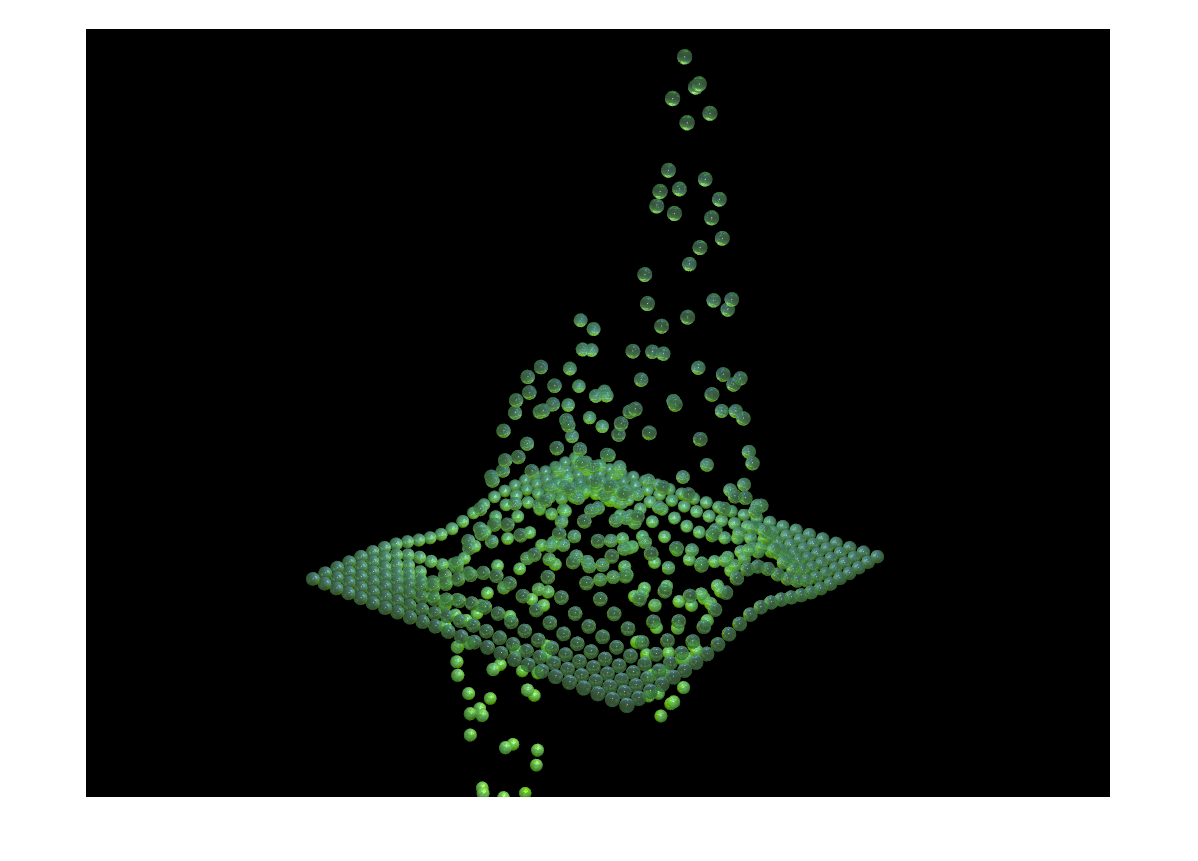

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 1866.845712 seconds.
